# **第十章 迁移学习**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **10.1 迁移学习简介**

        我们经常会遇到这样的问题：当我们利用现有的数据建立好模型后，将模型应用到一批新的样本数据上时，发现模型的预测精度降低了很多。这大多是由于训练集样本数据和测试集样本数据的分布不一样导致的（可能是由于环境、对象、数据采集设备/传感器等发生了变化）。那么，应该如何解决这个问题呢？常规地，如图1中的左图所示，需要在目标域（Target Domain）上从头开始，重新收集大量的训练集样本数据，然后训练模型，最后再进行预测。然而，这无疑是费时费力的，且有可能收集不到足够多的训练集样本数据。因此，我们需要寻找一种新的思路和方法来解决该问题。

        迁移学习（Transfer Learning）是一种机器学习方法，它利用从一个问题中学习到的知识来解决另一个相关但不同的问题。这种方法在深度学习中尤其有用，因为它可以显著减少训练新模型所需的数据量和计算资源。如图1中的右图所示，迁移学习的基本思想是借助源域（Source Domain）上的一个预训练模型（Pretrained Model），利用目标域上的少量数据对预训练模型进行微调（fine tuning），从而使得微调后的模型在完成目标域上的任务时具有较好的表现。

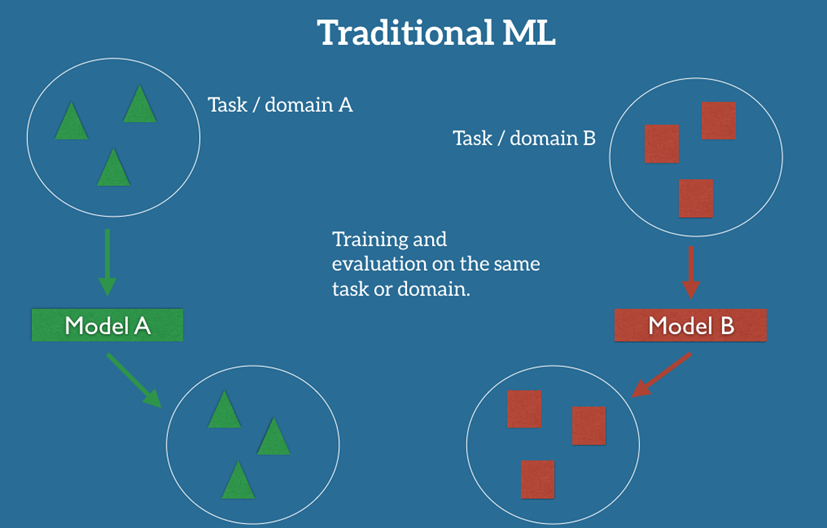   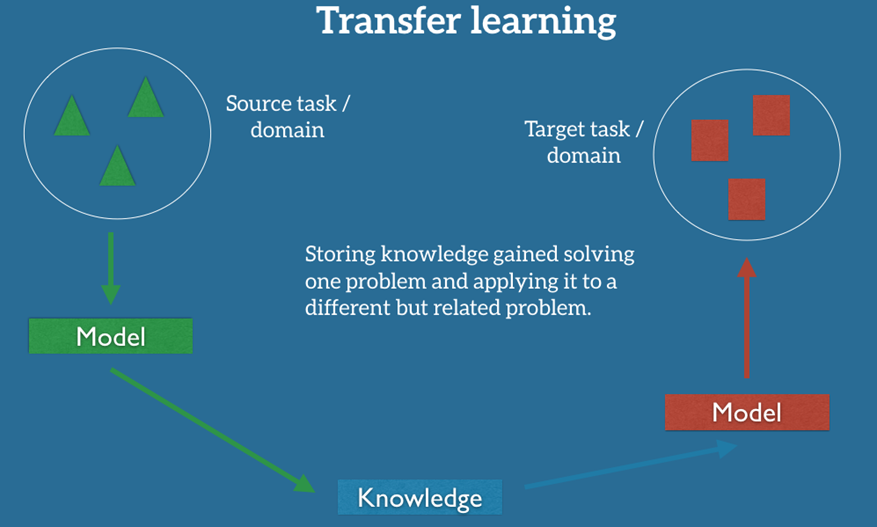

图1 传统机器学习与迁移学习的区别

        迁移学习的工作原理如图2所示，具体的训练算法步骤如下：

- **选择预训练模型：**根据目标任务的性质选择一个合适的预训练模型。例如，对于图像分类任务，可能会选择在ImageNet上预训练的CNN模型。

- **数据预处理：**对目标任务的数据进行适当的预处理，使其格式与预训练模型的输入格式一致。

- **模型重用：**保留预训练模型的大部分层，同时，根据目标任务的需求，可能需要替换或添加一些层（例如，更改输出层以匹配新任务的类别数）。

- **冻结与微调：**冻结预训练模型的一部分层，这意味着在训练过程中不更新这些层的权重。微调剩余的层（通常是顶层或输出层），以适应新的任务。

- **训练与优化：**在目标任务的数据集上训练模型，使用适当的损失函数和优化算法进行优化。

- **评估与调整：**在验证数据集上评估模型性能，根据需要调整模型结构或训练参数，以提高性能。

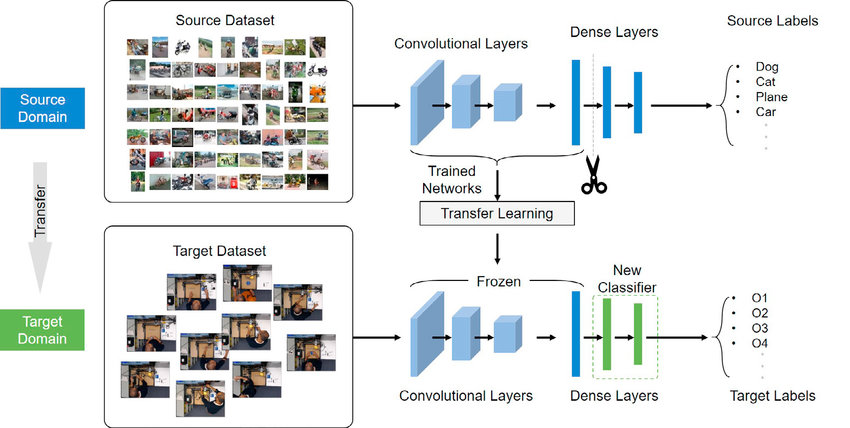

图2 迁移学习的工作原理

## **10.2 案例：基于AlexNet预训练模型的迁移学习**

- **导入数据**

        使用 'imageDatastore' 函数创建一个图像数据存储对象 'images' ，用于储存MerchData文件夹中所有子文件中的图像（每个子文件夹中15张照片，共75张照片），并提取每个子文件夹的名称作为相应图像的标签。

  images = imageDatastore('DogVsCat', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
  images.ReadFcn = @readFunctionTrain;

- **划分训练集与验证集**

        使用 'splitEachLabel' 函数从图像数据存储对象 'images' 中随机分割出训练集和验证集,默认70%作为训练集，30%作为验证集，可以根据需要调整这个比例。

  proportion = 0.7;
  [trainingImages,validationImages] = splitEachLabel(images,proportion,'randomized');

- **显示部分图片**

        使用 'randperm' 函数从训练集中随机选择 16 张图像，并将它们以 4x4 的方式显示在一个图像网格中，以便查看训练数据的样本，有助于了解数据的特点和内容。

  numTrainImages = numel(trainingImages.Labels);
  idx = randperm(numTrainImages,16);
  figure
  for i = 1:16
      subplot(4,4,i)
      I = readimage(trainingImages,idx(i));
      imshow(I)
  end

- **导入Alexnet预训练模型**

        创建一个预训练的AlexNet模型，并将其存储在变量 'net' 中。AlexNet是一个经典的卷积神经网络架构，通常用于图像分类任务。**注意：**如果未下载预训练的Alexnet模型，在导入之前需先去MathWorks官网下载Alexnet模型。

  net = alexnet;

  net.Layers

- **修改模型结构**

        在预训练的卷积神经网络Alexnet模型基础上构建一个新的迁移学习模型结构，新的模型包括预训练模型的卷积层，加上一个新的全连接层、Softmax 层和分类层，用于适应目标任务。在这个过程中，通过子函数 'freezeWeights' 将预训练模型的底层权重冻结，只有新添加的层的权重会在训练中更新。

  layersTransfer = net.Layers(1:end-3);
  numClasses = numel(categories(trainingImages.Labels));
  layers = [layersTransfer
            fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
            softmaxLayer
            classificationLayer];
      
  layers(1:end-3) = freezeWeights(layers(1:end-3));

- **设置模型训练参数**

        通过MATLAB工具箱中的 'trainingOptions' 函数，我们可以对迁移学习模型的训练选项进行配置。

  miniBatchSize = 10 , epochs = 10;
  numIterationsPerEpoch = floor(numel(trainingImages.Labels)/miniBatchSize);        % 计算每个周期的迭代次数
  options = trainingOptions('sgdm',...
                            'MiniBatchSize',miniBatchSize,...
                            'MaxEpochs',epochs,...
                            'InitialLearnRate',1e-4,...
                            'Verbose',false,...
                            'Plots','training-progress',...
                            'ValidationData',validationImages,...
                            'ValidationFrequency',numIterationsPerEpoch);

- **训练模型**

        使用前面配置的选项（options），通过训练数据集（trainingImages）和定义的迁移学习模型的网络结构（layers），来训练迁移学习模型。在训练过程中，模型将逐渐调整权重以适应目标任务，同时保留了预训练模型的通用特征。训练完成后， 'netTransfer' 将包含训练得到的模型，可以用于进行后续的评估。

  netTransfer = trainNetwork(trainingImages,layers,options);

- **模型预测**

        使用训练好的迁移学习模型 'netTransfer' 对验证数据集 'validationImages' 中的图像进行预测，并将预测的标签保存在 'predictedLabels' 中。

  predictedLabels = classify(netTransfer,validationImages);

- **显示部分预测结果**

        从验证集中选择指定索引的图像和对应的预测标签，然后将它们以 2x2 的方式显示在一个图像网格中，以便查看预测的结果，有助于了解模型在验证集上的表现和准确性。

  idx = [1 5 500 505];
  figure
  for i = 1:numel(idx)
      subplot(2,2,i)
      I = readimage(validationImages,idx(i));
      label = predictedLabels(idx(i));
      imshow(I)
      title(char(label))
  end

- **计算准确率**

        将预测的标签与真实的标签进行比较，计算正确预测的比例，从而得到模型在验证集上的性能评估。

  valLabels = validationImages.Labels;
  accuracy = mean(predictedLabels == valLabels)

## **Appendix-1：冻结参数子函数**

function layers = freezeWeights(layers)

    for ii = 1:size(layers,1)
        props = properties(layers(ii));
        for p = 1:numel(props)
            propName = props{p};
            if ~isempty(regexp(propName, 'LearnRateFactor$', 'once'))
                layers(ii).(propName) = 0;
            end
        end
    end

end

## **Appendix-2：读取图像子函数**

function I = readFunctionTrain(filename)

    I = imread(filename);       % 读取图像
    I = imresize(I, [227 227]); % 缩放图像

end
